specs = make_imaging_specs();
sys = build_imaging_system(make_imaging_specs());
sphere_mesh_dir = ('/Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/lnps_bem_solved/spherical_solutions/full_001_mesh.mat');
bleb_mesh_dir = ('/Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/lnps_bem_solved/blebbed_solutions/bleb_046_mesh.mat');

solve_bleb_population(mesh_dir, specs);

% Get camera noise

fn = ('/Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/testing_grid/blebgrid_22_22_mesh.mat');
%[particle_s, sol_s] = load_sphere_solution(sphere_mesh_dir, sys, 'full');
[particle_b, sol_b] = load_bleb_solution(bleb_mesh_dir, sys);

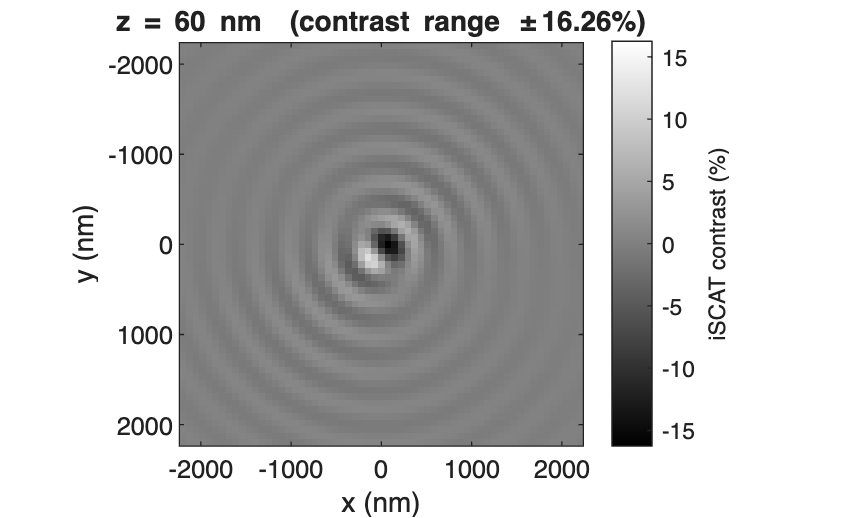

z = 60; %nm
lens = sys.lens;
[contrast, im, ibg] = propagate_iscat_image(sol, z, specs, farfields(sol, lens.dir), true);

specs = make_imaging_specs();
render_bleb_size_gradient('testing_grid', specs); 

render_bleb_size_gradient: CoreSizeNm=100.00 nm is not exactly on the grid -- using the nearest grid point, core index 18 (99.048 nm).
render_bleb_size_gradient: core index 18/22 (99.05 nm), 22 bleb sizes 10.0-120.0 nm, z = 50 nm, lnp_meshes/testing_grid/blebgrid_18_*_mesh.mat
-- solve pass --


render_mesh_size_gallery: 484 particles total, every 15 -> 32 targets ([15 30 45 60 75 90 105 120 135 150 165 180 195 210 225 240 255 270 285 300 315 330 345 360 375 390 405 420 435 450 465 480]) -- a missing target is nudged forward to the next existing particle
  [1/32] particle 15: core 10.0 nm / bleb 83.3 nm (testing_grid/blebgrid_01_15_mesh.mat)
  [2/32] particle 30: core 15.2 nm / bleb 46.7 nm (testing_grid/blebgrid_02_08_mesh.mat)
  [3/32] particle 45: core 20.5 nm / bleb 10.0 nm (testing_grid/blebgrid_03_01_mesh.mat)
  [4/32] particle 60: core 20.5 nm / bleb 88.6 nm (testing_grid/blebgrid_03_16_mesh.mat)
  [5/32] particle 75: core 25.7 nm / bleb 51.9 nm (testing_grid/blebgrid_04_09_mesh.mat)
  [6/32] particle 90: core 31.0 nm / bleb 15.2 nm (testing_grid/blebgrid_05_02_mesh.mat)
  [7/32] particle 105: core 31.0 nm / bleb 93.8 nm (testing_grid/blebgrid_05_17_mesh.mat)
  [8/32] particle 120: core 36.2 nm / bleb 57.1 nm (testing_grid/blebgrid_06_10_mesh.mat)
  [9/32] particle 135:

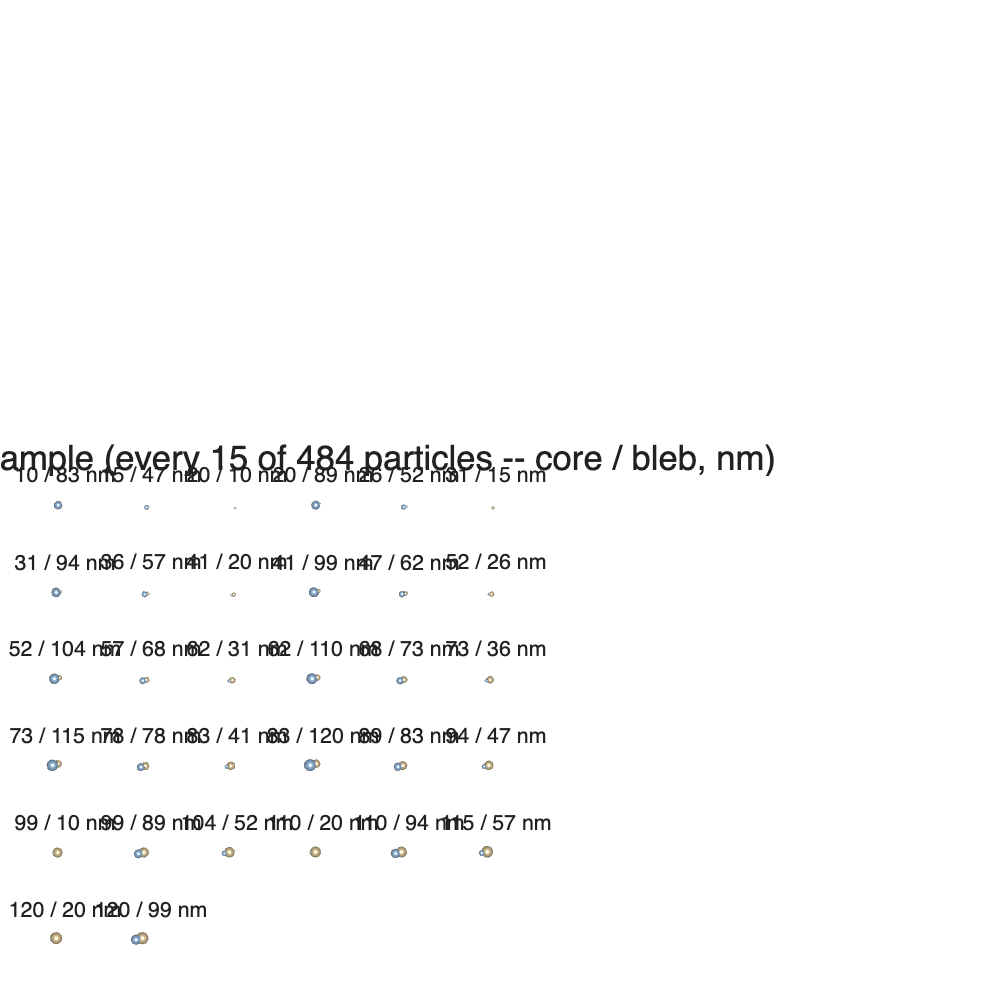

saved testing_grid/mesh_size_gallery.png


ans = struct with fields:
           idx: [15 30 45 60 75 90 105 120 135 150 165 180 195 210 225 240 255 270 285 300 315 330 345 360 375 390 405 421 435 450 465 480]
     coreIndex: [1 2 3 3 4 5 5 6 7 7 8 9 9 10 11 11 12 13 13 14 15 15 16 17 18 18 19 20 20 21 22 22]
     blebIndex: [15 8 1 16 9 2 17 10 3 18 11 4 19 12 5 20 13 6 21 14 7 22 15 8 1 16 9 3 17 10 3 18]
    coreSizeNm: [10 15.2381 20.4762 20.4762 25.7143 30.9524 30.9524 36.1905 41.4286 41.4286 46.6667 51.9048 51.9048 57.1429 62.3810 62.3810 67.6190 72.8571 72.8571 78.0952 83.3333 83.3333 88.5714 93.8095 99.0476 99.0476 104.2857 109.5238 … ] (1×32 double)
    blebSizeNm: [83.3333 46.6667 10 88.5714 51.9048 15.2381 93.8095 57.1429 20.4762 99.0476 62.3810 25.7143 104.2857 67.6190 30.9524 109.5238 72.8571 36.1905 114.7619 78.0952 41.4286 120 83.3333 46.6667 10 88.5714 51.9048 20.4762 93.8095 … ] (1×32 double)
            ok: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
           fig: [1×1 Figure]
    figure

render_mesh_size_gallery('testing_grid')

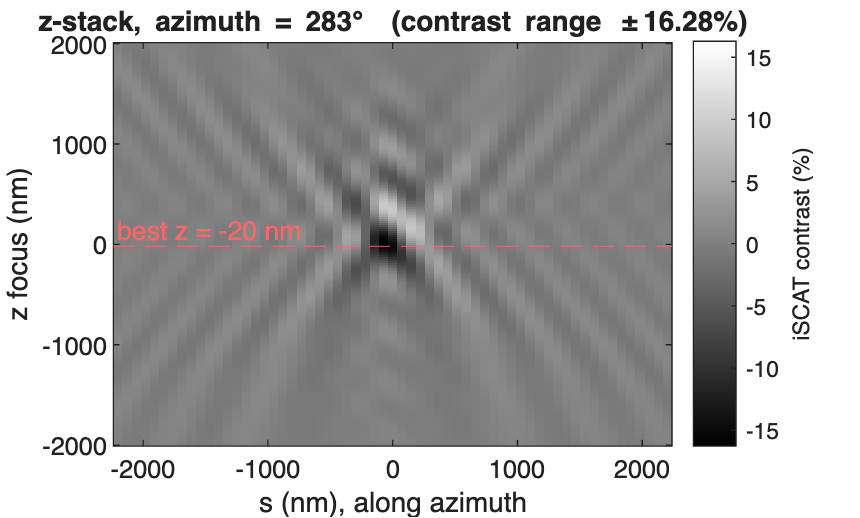

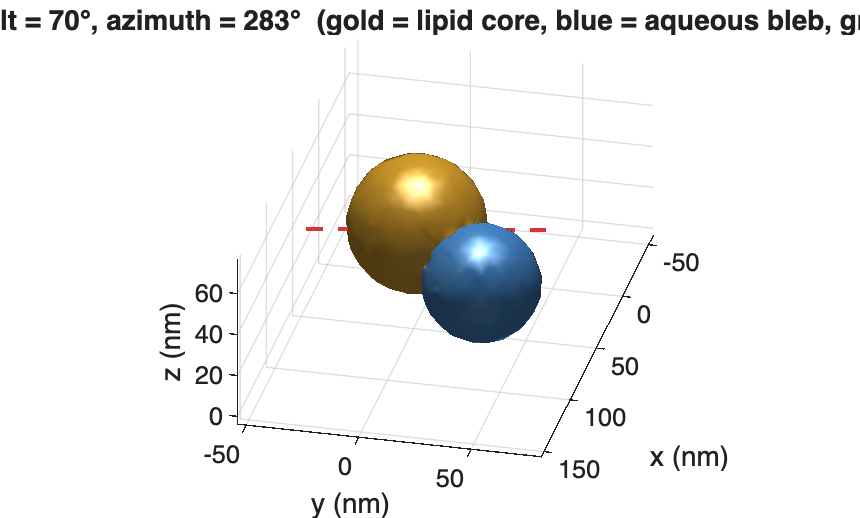

z_scan = -2000:20:2000;
propagate_iscat_zstack(particle, sol, sys, z_scan, 'Display', true);

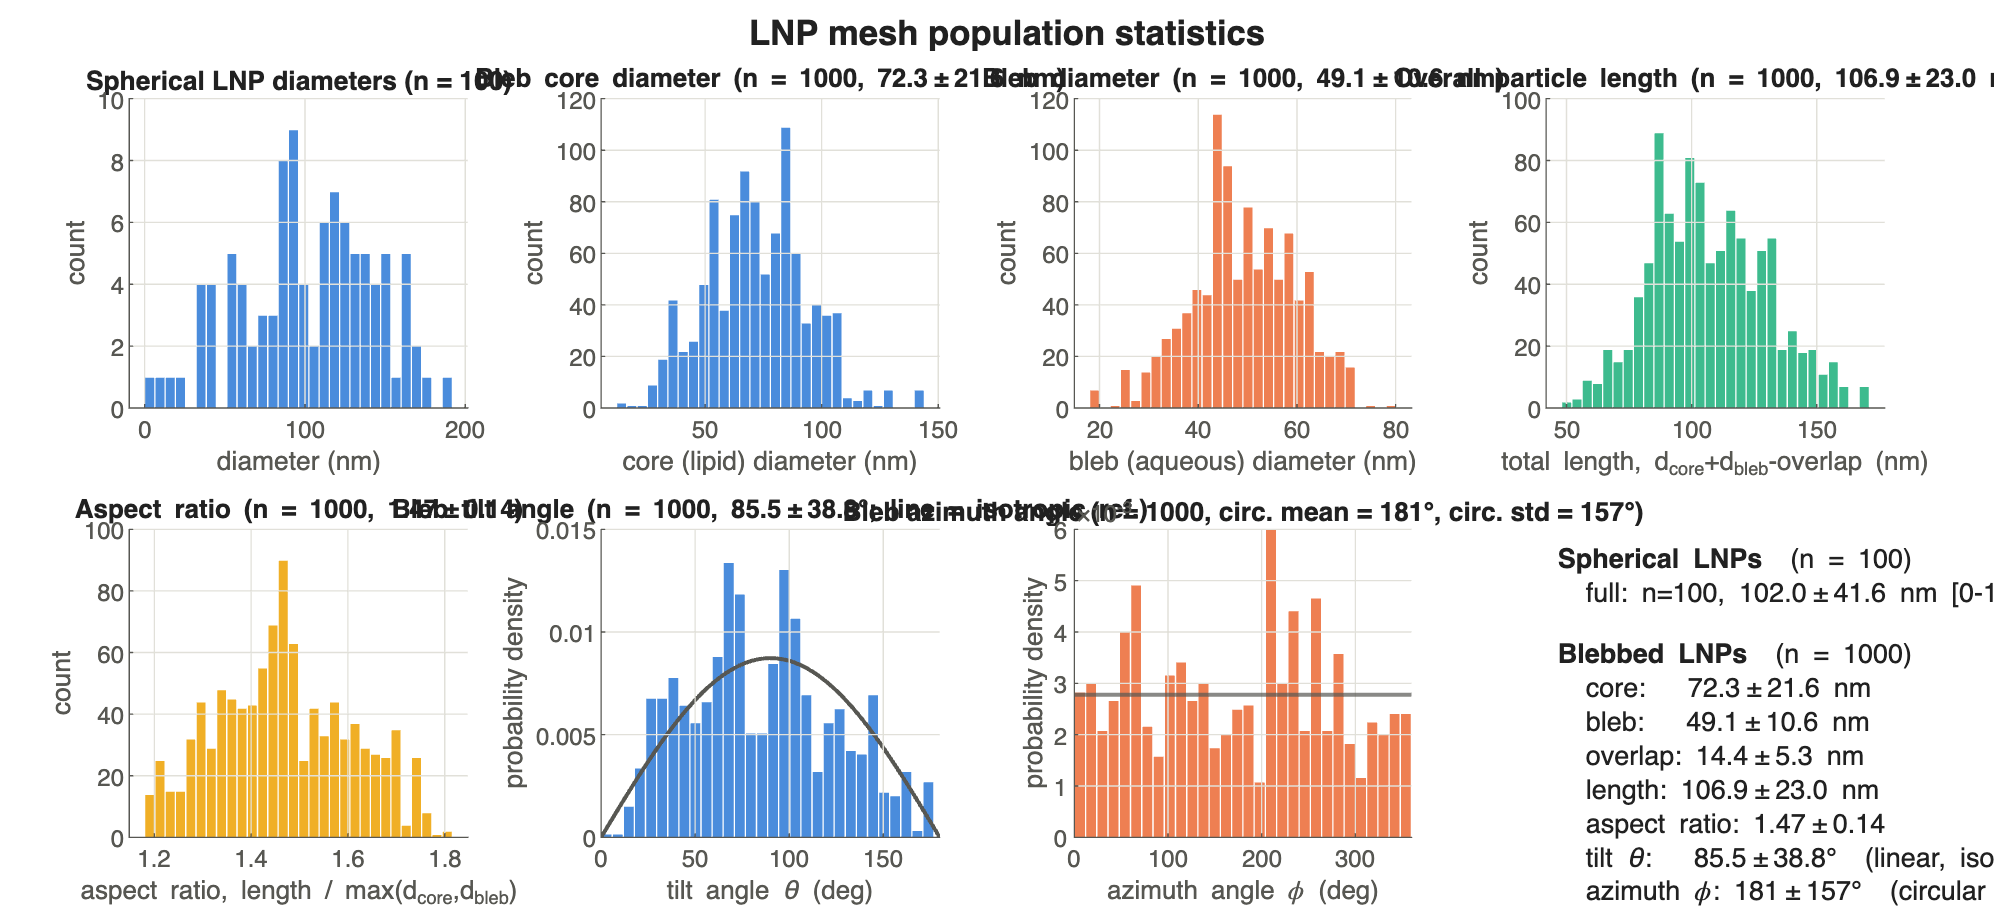

stats = plot_lnp_mesh_stats(sphere_mesh_dir, bleb_mesh_dir);

[~, sweep] = render_iscat_zstack_video(particle, sol, sys, z_scan, 'azimuth_zstack.mp4');

wrote azimuth_zstack.mp4 (72 frames)


render_particle_landing_video(particle, sys, 'azimuth_landing.mp4', 'AzimuthList', sweep.azimuth_deg);

wrote azimuth_landing.mp4 (72 frames)


outS = propagate_iscat_rvt_zstack(sphere_mesh_dir, specs, z_scan);
outB = propagate_iscat_rvt_zstack(bleb_mesh_dir, specs, z_scan);


out = propagate_iscat_rvt_zstack(bleb_mesh_dir, specs, z_scan, ...
          'MakeVideo', true, 'VideoFile', 'bleb_001_rvt.mp4');

vecS = calculate_rvt_vector(outS, 'Display', true);
vecB = calculate_rvt_vector(outB, 'Display', true, 'Axes', vecS.ax, ...
           'Color', '#eb6834', 'DisplayName', 'bleb 001');

% wouldnt be as robust to tilt
% need to take probably an overall tilt like flat field vector